# **HOMEWORK # 1**

# Numerical Opmitization - 2022

## Sebastian Aguilera Novoa

##     1.  Infimum

        Let $A \subset \mathbb{R}$, such that $\textrm{inf} \; A$ is finite or $\textrm{inf} \; A = -\infty$. Prove that there is a sequence $(a_n)_{n\in \mathbb{N}} $ of elements in $A$ such that $a_n \to \textrm{inf} \; A$ when $n\to \infty$.

Let's divide the prove in two

- The infimum is finite, $c= \textrm{inf} \; A$. Remembering the definition of the infimum, $\forall \varepsilon>0:\exists x \in A \;\text{s.t.}\; x\leq c+\varepsilon$, it means that there is some constant bigger than zero such that when it is added to the infimum, the new value is bigger than an element of $A$, e.i., when some $\varepsilon$ is add to the infimum the result is an element of $A$. In particular, if $\varepsilon=1/n$ and we consider a squence $(a_n)_{n\in \mathbb{N}} = 1/n$ of elements in $A$, when $n \to \infty$ the sequence goes to the infimum, $a_n \to\textrm{inf} \; A$.

- The infimum is not finite, $c=\textrm{inf} \; A = -\infty$. In this case, considering the definition of the infimum, $\forall x\in A: c\leq x$, and a sequence of elements of $A$ $(a_n)_{n\in \mathbb{N}} = -n$, when $n$ goes to $\infty$ then the sequence tends to the infimum,  $a_n \to \textrm{inf} \; A$ when $n\to \infty$.    

##     2. Level Set

        Suppose that $\Omega$ is a not empty **closed** set and $f$ is a **continious** and **cohercive** function in $\Omega$. Prove that given $R>0$ the set


$$\Omega_R := \{x\in \Omega | f(x) \leq R\}$$


        is closed and bounded.

In order to prove that $\Omega_R$ is closed, let's prove that its complement is open $\Omega_R^C$, by defition


$$\Omega_R^C := \{x\in \Omega | f(x) > R\}$$


now using the continuity of $f$ at a point $c$ of its domain $\Omega$, for any neighborhood over te image of $c$, $N_1(f(c))$, there is a neighborhood $N_2(c)\in \Omega$ such that $f(x) \in N_1(f(c))$ whenever $x \in N_2(c)$, it is equivalent to say that for any $\epsilon>0$ and $c\in \Omega$ there is $B_\epsilon(f(c))\subseteq \Omega_R^C$ such that $B_\epsilon(c)\subseteq \Omega$. Since every point in $\Omega_R^C$ is the center of an open ball contained in $\Omega_R^C$ then it is an open set and then $\Omega_R$ is a closed set.

Again, using the definition of continuty there is some pre-image $\tilde{x}$ of $R$ ($f(\tilde{x})=R$]) such that allow to us rewrite the defition of $\Omega_R$ as follows


$$\Omega_R := \{x\in \Omega | f(x) \leq f(\tilde{x})\}$$


this also implies that $f(\tilde{x})$ is the suprem of  $\Omega_R$. Now, using the defition of cohercivity, $\lim_{|x||\to\infty}f(x) = + \infty$, for any $x$ far way from origin there is always an image and then the supremum and infimum always exists that implies that $\Omega_R$ is bounded.

Then, it has been demostrated that $\Omega_R$ is closed and bounded. □

Using the continuty, there is some positive real number $\delta >0$ such that for all $x$ in the domain of $f$ with $x_{0}-\delta <x<x_{0}+\delta$, so the value of $f(x)$ satisfies$f\left(x_{0}\right)-\varepsilon <f(x)<f(x_{0})+\varepsilon $, for any $x\in \Omega_R$ thgere is some $\delta >0$

## 3. Quadratic Optimization

Prove that the quadratic optimization problem

 
$$ \min _{x \in \Omega} x^{T} Q x+c^{T} x $$


 where $\Omega \subset \mathbb{R}^n$ is a closed set, $x,c \in \mathbb{R}^n$ and the matrix $Q \in \mathbb{R}^{n\times n}$, admit at least one global solution.

Using the Taylor's theorem


$$f(x+p) = f(x)+\nabla f(x+tp)^Tp, \qquad t\in [0,1]$$



$$f(x+p)= (x+p)^{T} Q (x+p)+c^{T} (x+p)
= x^{T}Q x+p^T Q p + 2x^TQ p +c^{T} x+c^{T}p$$



$$\nabla f(x+tp)^Tp =  (2(x+tp)^{T} Q +c^{T}) p  =
2x^{T} Qp+tp^{T} Qp +c^{T}p  $$


then the theorem is


$$x^{T}Q x+p^T Q p + 2x^TQ p +c^{T} x+c^{T}p =  x^{T} Q x+c^{T} x  + 2x^{T} Qp+tp^{T} Qp +c^{T}p  $$


which implies that $f$ satisfies the necessary conditions for optimality.

Convexity

Let $f(x)= x^{T} Q x+c^{T} x $, $x_1, x_2 \in \Omega
$, and consider any point on the line joining these points $z = (1-t) x_1 + tx_2, \quad t\in[0,1]$.


$$f(z)=( (1-t) x_1 + tx_2)^{T} Q ( (1-t) x_1 + tx_2)+c^{T} ( (1-t) x_1 + tx_2)\\
= ( (1-t) x_1^{T} + tx_2^{T}) Q ( (1-t) x_1 + tx_2)+  (1-t) c^{T}x_1 + t c^{T}x_2\\
=  (1-t)^2 x_1^{T} Q x_1 + t^2 x_2^{T} Q x_2 + 2 (1-t) t x_1^T Q x_2+  (1-t) c^{T}x_1 + t c^{T}x_2\\
=  (1-t) [(1-t) x_1^{T} Q x_1 + c^{T}x_1] + t [t x_2^{T} Q x_2 +c^{T}x_2] + 2 (1-t) t x_1^T Q x_2\\
\leq  (1-t) [ x_1^{T} Q x_1 + c^{T}x_1] + t [ x_2^{T} Q x_2 +c^{T}x_2] + 2 (1-t) t x_1^T Q x_2 =(1-t) f(x_1)+ tf(x_2)+ 2 (1-t) t x_1^T Q x_2$$


## 4.  Circle minimization

Given a set of $n$ points in the plane. Find the circle of minimum radius containing all these points.

## a) 

Consider this problem as a constrained optimization problem with a linear objective function and quadratic constraints.

Let $n$ points in the plane $z=(x_i,y_i)\in\mathbb{R}^2$, with $i=1,\dots,n$. The center of these points is the point $(x_c,y_c)$ defined as


$$x_c =\frac{1}{n}\sum_{i=1}^n x_i, \qquad y_c =\frac{1}{n}\sum_{i=1}^n y_i$$


Then, the problem of fin the minimum circle that enclose the $n$ points can be formulated as follows


$$\;\qquad \underset{r\in \mathbb{R}}{min} \quad r\\
\text { subject to }  \quad \;(x_i-x_c)^2+(y_i-y_c)^2  \leq r^2, \qquad i=1,\dots,n$$


where the objective function is lineal and the constraints is quadratic.

clear; clc;
import casadi.*

n = 50;
rng(1)
xi = 10*rand(n,1);   yi = 10*rand(n,1);
xc = (1/n)*sum(xi);   yc = (1/n)*sum(yi);

opti = casadi.Opti();
r = opti.variable(); 
opti.minimize(r);

opti.subject_to(sqrt((xi-xc).^2+(xi-xc).^2)  <= r*ones(n,1));
%opti.subject_to((xi-xc).^2+(xi-xc).^2  <= r^2*ones(n,1));

opti.solver('ipopt');

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:       50
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        1
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:       50
        inequality constraints with only lower bounds:       50
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

ropt = sol.value(r)

ropt = 7.3806

rreal = 4.8798

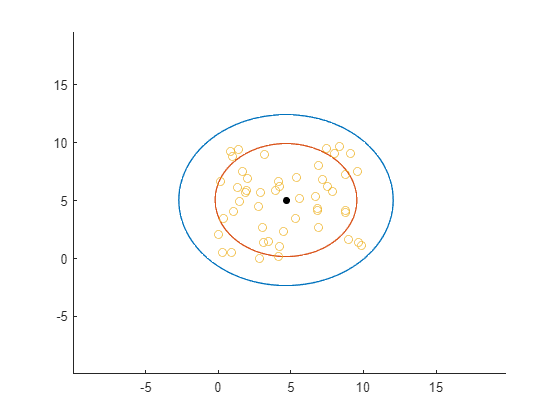

clf;
hold on
th = 0:pi/50:2*pi;
xunit = ropt  * cos(th) + xc;
yunit = ropt  * sin(th) + yc;
plot(xunit, yunit);

plot(xi,yi, 'o')
plot(xc,yc, 'k.','MarkerSize',16)
xlim([-10+min(xi) 10+max(xi)]); ylim([-10+min(yi) 10+max(yi)]);
hold off

## b)

Prove that the problem has unique solution.

## 5.  Bag

Let $S=\{1,2,...,M \}$ a set of $M$ objects, with $p_i$ the weight of the $i$-th object and $v_i$ its value $i=1,2,...,M $    . It is a matter of carrying in a bag objects from $S$, such that the total value is maximized, but without the total weight of all the objects to be included in the bag  exceeding a given weight $P$. Formulate the optimization problem that allow to solve the problem.

## 6. Sets Convexity

Study which of the following subsets are convex

### a) $ S = \{ (x_1,x_2) \in \mathbb{R}^2 | x_2 \geq x_1 \}$

In order to check if $S$ is convex let's rewrite the set as follows


$$S = \{ (x_1,x_2) \in \mathbb{R}^2 | x_2 -x_1 = A \cdot x \geq 0 \}$$
 

where $A = (-1,1)$ and $x=(x_1,x_2)$ are two vectors.

Let $x,y\in S$, i.e., $A \cdot x \geq 0, \; A \cdot y \geq 0$ with $x=(x_1,x_2)$ and $y=(y_1,y_2)$. Now, consider any point on the line joining points $x$ and $y$


$$z = (1-t) x + ty, \quad t\in[0,1]$$


and operating$A$ to left side


$$Az = (1-t) Ax + tAy$$


since all the terms are greater or equal to zero, from the definition of $t$ and the definition of an element of $S$, then


$$Az = (1-t) Ax + tAy \geq 0$$


which is the condition to be in $S$, $z\in S$. Then, the set $S$ is a convex set.

### b) $S = \{ (x_1,x_2) \in \mathbb{R}^2 | x_1^2+x_2^2 <4 \}$

Analogous to the previous point,


$$S = \{ (x_1,x_2) \in \mathbb{R}^2 |\; ||x||^2 <4 \}= \{ x \in \mathbb{R}^2 | \; ||x|| < 2\}$$


Let $x,y\in S$, i.e., $||x||<2, ||y||<2$, and consider any point on the line joining points


$$z = (1-t) x + ty, \quad t\in[0,1]$$


In order to prove that $S$ is convex, consider the norm of the vector 


$$||z||^2 = ((1-t) x + ty)^T ((1-t) x + ty) = ((1-t) x^T + ty^T) ((1-t) x + ty)\\
||z||^2 = (1-t)^2 x^T x + t^2 y^T y + 2(1-t)t x^T y = (1-t)^2 ||x||^2 + t^2 ||y||^2 + 2(1-t)t x^T y$$


using the Cauchy–Schwarz inequality 


$$||z-2||^2 \leq (1-t)^2 ||x||^2 + t^2 ||y||^2 + 2(1-t)t ||x|| \; ||y||$$


using the pertenence condition of $S$ ($x$ and $y$ statement conditions)


$$||z-2||^2 \leq (1-t)^2 (4) + t^2 (4) + 2(1-t)t (4) = 4(1-2t+t^2+t^2+2t-2t^2)$$


Finally simplifying,


$$\Rightarrow ||z-2||^2 \leq 4$$


This result means that $z$ is in $S$, $z\in S$>. Then, the set $S$ is convex. 

### c) $S = \{ (x_1,x_2) \in \mathbb{R}^2 | x_2 = \sin x_1\}$

In order to prove that $S$ is not convex, let $x=(0,0)$ and $y=(\pi,0)$ two points in $S$ and consider any point on the line joining points


$$z = (1-t) x + ty = (1-t)(0,0)+t(\pi,0), \quad t\in[0,1]\\
z = t(\pi,0)$$


In particular taking $t=1/2$, $z = (\pi/2,0)$, the point $z$ does not live in $S$ since $\sin \pi/2 \neq 0$. Then, the set $S$is not convex since $z\notin S$ although$x$ and $y$ if ther are in $S$.

### d) $S = \{ y \in \mathbb{R}^m \;:\; y=Ax, \;x\in C \} \text{with }\; C\subseteq \mathbb{R}^n  \;\text{convex and } \;A \;\text{a matrix} \;m\times m$

Let $y_1, y_2 \in S$, i.e., $y_1 = A x_1$ and $y_2 = A x_2$. and consider any point on the line joining points


$$z = (1-t) y_1 + ty_2, \quad t\in[0,1]\\
z = (1-t) Ax_1 + tAx_2 = A\left[(1-t) x_1 + tx_2\right] = A \tilde{x}$$


where $\tilde{x}$ is any point on the line joining points $x_1$ and $x_2$ that live in $C$, since it is convex $\tilde{x}\in C$and then $z$ satisfies the condition to pertenence to $S$, $z=A\tilde{x}$, with $\tilde{x}\in C$.